# SLCO4A - Aula Prática 7

## Análise de sistemas no domínio do tempo

### Resposta impulsiva 

O significado de **resposta impulsiva** ou **resposta ao impulso** de um sistema é facilmente derivado se considerarmos os termos dos quais ele é nomeado. O termo 'resposta', denota a saída de um sistema, enquanto o termo 'impulso', indica que o sinal de entrada aplicado ao sistema é o impulso unitário ou função delta de Dirac. A resposta ao impulso é usualmente denotada por $h\left(t\right)\ldotp$ Matematicamente,


$$h\left(t\right)=S\left\lbrace \delta \left(t\right)\right\rbrace$$


Conhecida a resposta ao impulso de um sistema pode-se conhecer a resposta de saída para qualquer entrada arbitrária aplicada no sistema, por meio da operação de convolução.

### Convolução de tempo contínuo

A resposta de saída de um sistema para qualquer entrada é computada pela convolução do sinal de entrada com a resposta ao impulso do sistema.


$$y\left(t\right)=x\left(t\right)*h\left(t\right)$$



$$y\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)h\left(t-\tau \;\right)d\tau \;$$


#### Cômputo da convolução

**Exemplo**: Considere um sistema LIT descrito por uma resposta ao impulso 


$$h\left(t\right)=\left\lbrace \begin{array}{ll}
1-t, & 0\le \;\;t\le 1\\
0, & \textrm{cc}
\end{array}\right.$$


Calcule a resposta do sistema para o sinal de entrada


$$x\left(t\right)=\left\lbrace \begin{array}{ll}
1, & 0\le \;\;t\le 2\\
0, & \textrm{cc}
\end{array}\right.$$


**Passo 1** - Obter o sinal de entrada e a resposta ao impulso em função de $\tau \;$


$$x\left(\tau \;\right)=\left\lbrace \begin{array}{ll}
1, & 0\le \;\;\tau \;\le 2\\
0, & \textrm{cc}
\end{array}\right.$$



$$h\left(\tau \;\right)=\left\lbrace \begin{array}{ll}
1-\tau \;, & 0\le \;\;\tau \;\le 1\\
0, & \textrm{cc}
\end{array}\right.$$


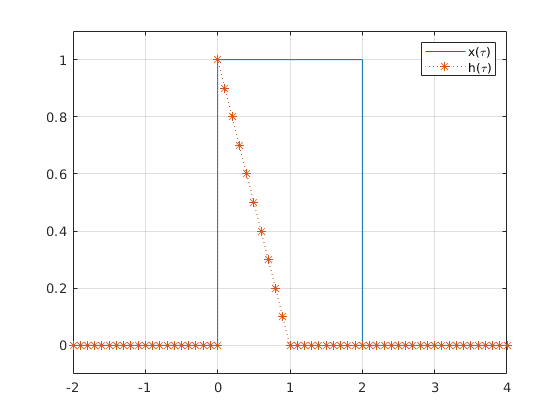

% Definindo x
tx1=-2:0.1:0;
tx2=0:0.1:2;
tx3=2:0.1:4;
x1=zeros(size(tx1));
x2=ones(size(tx2));
x3=zeros(size(tx3));
tx=[tx1 tx2 tx3];
x=[x1 x2 x3];

% Definindo h
th1=-2:0.1:0;
th2=0:0.1:1;
th3=1:0.1:4;
h1=zeros(size(th1));
h2=1-th2;
h3=zeros(size(th3));
th=[th1 th2 th3];
h=[h1 h2 h3];
figure
plot(tx, x, th, h, ":*")
ylim([-0.1 1.1])
legend('x(\tau)', 'h(\tau)')
grid on

**Passo 2** - Realizar a reflexão de um dos sinais.

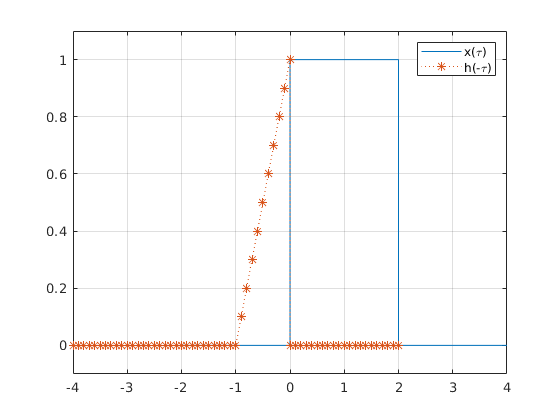

plot(tx, x, -th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(-\tau)')
grid on

**Passo 3** - Realizar o deslocamento de $t$ do sinal refletido $h\left(-\tau \;\right)\Rightarrow h\left(t-\tau \;\right)$.

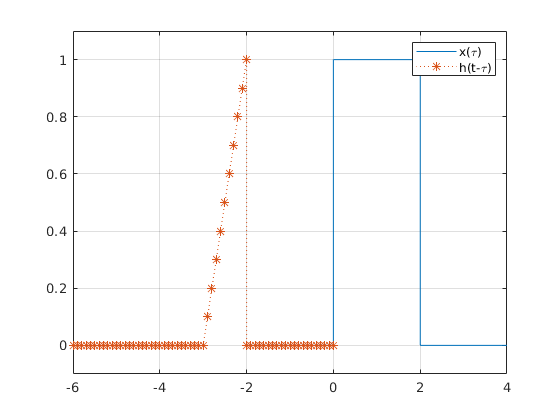

t=-2;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on

**Passo 4** - Realizar o deslizamento.

*Primeiro estágio: sem sobreposição*

t=-2;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on

*Segundo estágio: sobreposição parcial*

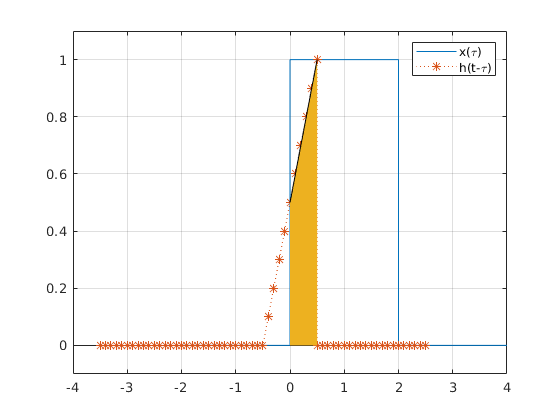

t=0.5;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on
T=1;
r=0:0.1:t; % h(t)=1-t
a=1-t/T+r/T; % h(t - tau)=1-(t-tau)=1-t+tau
hold on
area(r, a);
hold off
legend('x(\tau)', 'h(t-\tau)')

*Terceiro estágio: sobreposição completa*

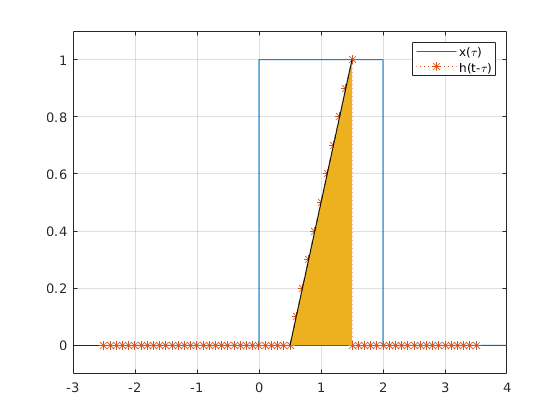

t=1.5;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on
T=1;
r=t-T:0.1:t; % h(t)=1-t
a=1-t/T+r/T; % h(t - tau)=1-(t-tau)=1-t+tau
hold on
area(r, a);
hold off
legend('x(\tau)', 'h(t-\tau)')

*Quarto estágio: saída - sobreposição parcial*

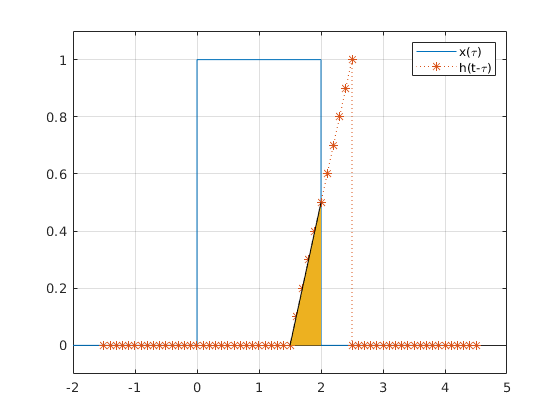

t=2.5;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on
T=1;
r=t-T:0.1:2; % h(t)=1-t
a=1-t/T+r/T; % h(t - tau)=1-(t-tau)=1-t+tau
hold on
area(r, a);
hold off
legend('x(\tau)', 'h(t-\tau)')

*Quinto estágio: sem sobreposição*

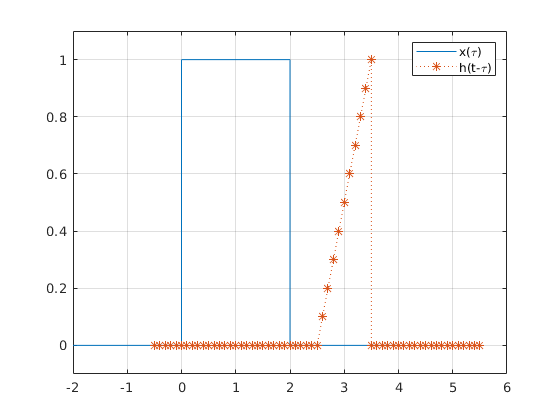

t=3.5;
plot(tx, x,t - th, h, ":*");
ylim([-0.1 1.1])
legend('x(\tau)', 'h(t-\tau)')
grid on

**Passo 5** - Especificação dos limites e cálculo da integral de convolução.

- $t<0$: sem sobreposição, $y\left(t\right)=$0

- $0<t<1$**: início da sobreposição**


$$y\left(t\right)=\int_0^t 1\left(1-\left(t-\tau \;\right)\right)\;\;d\tau =\int_0^t 1-t+\tau \;\;d\tau$$


syms t r % tal = r
f=1-t+r

$$f = r-t+1$$

int(f, r, 0, t) % -t^2/2+2t

$$ans = -\frac{t\,\left(t-2\right)}{2}$$

- $1<t<2$**: sobreposição completa**


$$y\left(t\right)=\int_{t-1}^t 1-t+\tau \;\;d\tau$$


int(f, r, t - 1, t) 

$$ans = \frac{1}{2}$$

- $2<t<3$**: sobreposição parcial - estágio de saída**


$$y\left(t\right)=\int_{t-1}^2 1-t+\tau \;\;d\tau$$


int(f, r, t-1, 2)

$$ans = \frac{{\left(t-3\right)}^{2}}{2}$$

- $t>3$: sem sobreposição, $y\left(t\right)=0$

0;

**Plot de **$y\left(t\right)$

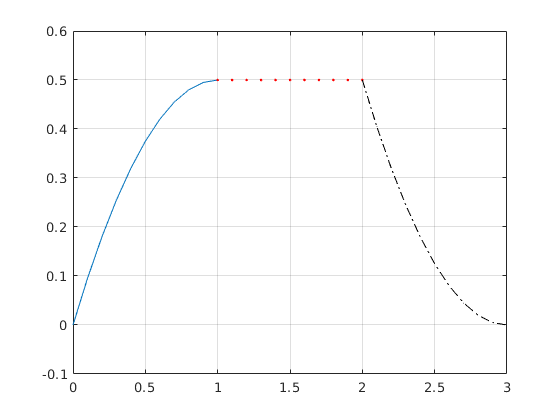

t1=0:0.1:1;
t2=1:0.1:2;
t3=2:0.1:3;
y1=-t1.^2/2+t1;
y2=0.5;
y3=(t3-3).^2/2;
t=[t1 t2 t3];
y=[y1 y2 y3];
plot(t1, y1, t2, y2, '.r', t3, y3, '-.k')
ylim([-0.1 0.6])
grid

#### Comando conv

- **Primeira regra**: os dois sinais devem ser definidos no mesmo intervalo, $a\le t\le b$, no qual um dos sinais é diferente de zero em cada extremo do intervalo.

- **Segunda regra:** quando o sinal consiste de múltiplas partes, o intervalo em que cada parte é definidda não deve ser sobreposta. Por exemplo,


$$h\left(t\right)=\left\lbrace \begin{array}{ll}
1-t, & 0\le \;\;t\;\le 1\\
0, & 1<t\;\le 2
\end{array}\right.$$



$$x\left(t\right)=\left\lbrace \begin{array}{ll}
1, & 0\le \;\;t\le 2\\
0, & t>2
\end{array}\right.$$


step=0.01;
t=0:step:2;
x=ones(size(t));
ta=0:step:1;
tb=1+step:step:2;
ha=1-ta;
hb=zeros(size(tb));
h=[ha hb];

- **Terceira regra: **A saída do comando `conv` deve ser multiplicada pela passo de incremento `step `usado na definição dos sinais.

y=conv(x, h)*step;
length(y)

ans = 401

length(x)

ans = 201

length(h)

ans = 201

- **Quarta regra: **A saída do sistema é plotada com o dobro do intervalo em que cada um dos sinais de entrada e resposta impulsiva foram definidos.

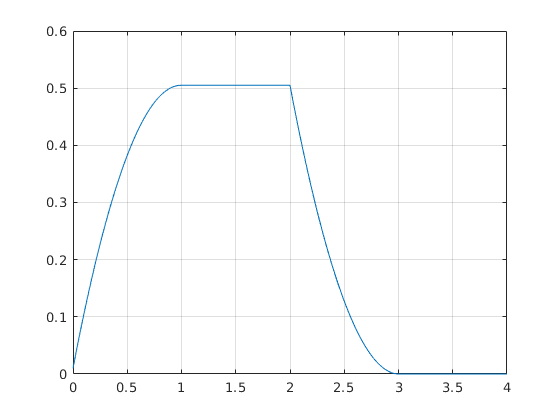

ty=0:step:4;
plot(ty, y)
grid on

#### Deconvolução

Considerando os mesmos sinais do exemplo anterior, suponha que desejamos determinar a resposta impulsiva a partir do sinal de entrada $x\left(t\right)$e do sinal $y\left(t\right)$.

h(t)=deconvolucao(y(t), x(t))

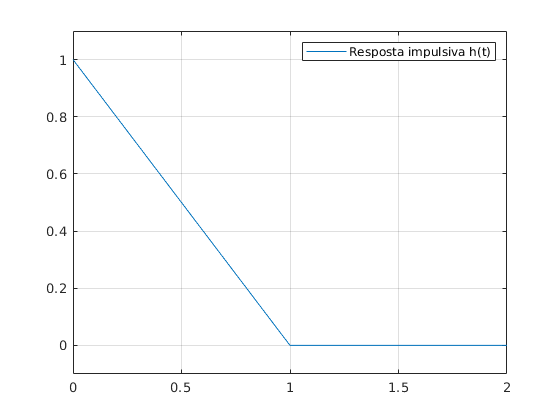

hh=deconv(y, x)*1/step;
plot(t, hh)
ylim([-0.1 1.1])
legend('Resposta impulsiva h(t)')
grid on

### Exemplos

Compute a convolução entre os sinais 

$x\left(t\right)=h\left(t\right)=1$, $1\le t\le 2$

$x\left(t\right)=h\left(t\right)=0$, $0\le \;t<1$ e $2<t\le 10$

### Propriedades da convolução

- Comutativa


$$h_1 \left(t\right)*h_2 \left(t\right)=h_2 \left(t\right)*h_1 \left(t\right)$$


**Exemplo**: Verifique a propriedade de comutação é válida para os seguintes sinais $h_1 \left(t\right)=1$, $h_2 \left(t\right)=2e^{-2t}$, $0\le t\le 5$.

t=0:0.01:5;
h1=ones(size(t));
h2=2*exp(-2*t);
% y=h1*h2
y=conv(h1, h2)*0.01;
figure
plot(0:0.01:10, y, "LineWidth",1)
hold on
grid on
% z = h2*h1
z=conv(h2, h1)*0.01;
plot(0:0.01: 10, z, "r-.", "LineWidth",2);
legend("h1*h2", "h2*h1")

- Associativa


$$h_2 \left(t\right)*\left\lbrack h_1 \left(t\right)*x\left(t\right)\right\rbrack =\left\lbrack h_2 \left(t\right)*h_1 \left(t\right)\right\rbrack *x\left(t\right)$$


**Exemplo: **Verifique a propriedade associativa da convolução supondo que $h_1 \left(t\right)=\frac{1}{\pi \;}t$, $h_2 \left(t\right)=2e^{-2t}$, $0\le t\le 5$ e $\;x\left(t\right)=u\left(t\right)-u\left(t-5\right)\ldotp$

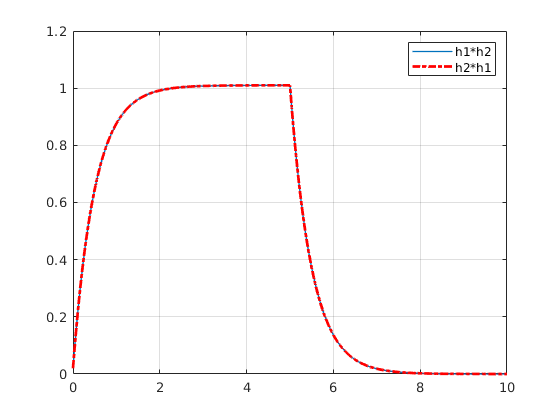

t=0:0.01:5;
x=ones(size(t));
h1=1/pi*t;
% y1=h1*x
y1=conv(h1, x)*0.01;
h2a=2*exp(-2*t);

thb=5:0.01:10;
h2b=zeros(size(thb));
h2=[h2a h2b];
% y=h2*y1
y = conv(h2, y1)*0.01;
figure
plot(0:0.01:20.01, y)
grid on
hold on

% z=[h2*h1]*x
t=0:0.01:5;
h1=1/pi*t;
h2=2*exp(-2*t);
% z1=[h2*h1]
z1=conv(h1, h2)*0.01;
xa=ones(size(t));
txb=5.01:0.01:10;
xb=zeros(size(txb));
x=[xa xb];
z=conv(z1, x)*0.01;
plot(0:0.01:20, z, "r-.")
grid on
legend("h2*[h1*x]", "[h1*h2]*x")

- Distributiva


$$\left\lbrack h_2 \left(t\right)+h_1 \left(t\right)\right\rbrack *x\left(t\right)=h_1 \left(t\right)*x\left(t\right)+h_2 \left(t\right)*x\left(t\right)$$


**Exemplo: **Verifique a propriedade associativa da convolução supondo que $h_1 \left(t\right)=\cos \left(\pi \;t\right)$, $h_2 \left(t\right)=2e^{-2t}$, $0\le t\le 5$ e $\;x\left(t\right)=u\left(t\right)-u\left(t-5\right)\ldotp$